
% reading the image
Image=imread('C:\Users\Sandeep\Downloads\messi.jpg')

Image = 675×1200×3 uint8 array
Image(:,:,1) =

    98   130   163   174   178   182   188   189   194   191   187   183   178   167   156   144   116    86    47    19    10     6     5     1     2     2     2     2     2     2     3     3     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     3     3     2     2     2     1     1     3     1     8     9    21    60    93   115   128   137   148   165   173   175   175   179   184   179   170   160   141   127   117    85    41    11     7     4     2     2     3     2     1     2     2     2     2     2     2     2     2     1     2     2     3     3     2     2     1     1     1     1     2     2     3     3     3     5     3     3     2     2     1     1     1     5     8    24    49    76    97   114   127   144   152   158   156   154   153   151   149   132   125   110    92    72    50    28    14     4     2     2     1     1     2     2     3     4     4     4     3     3     2     

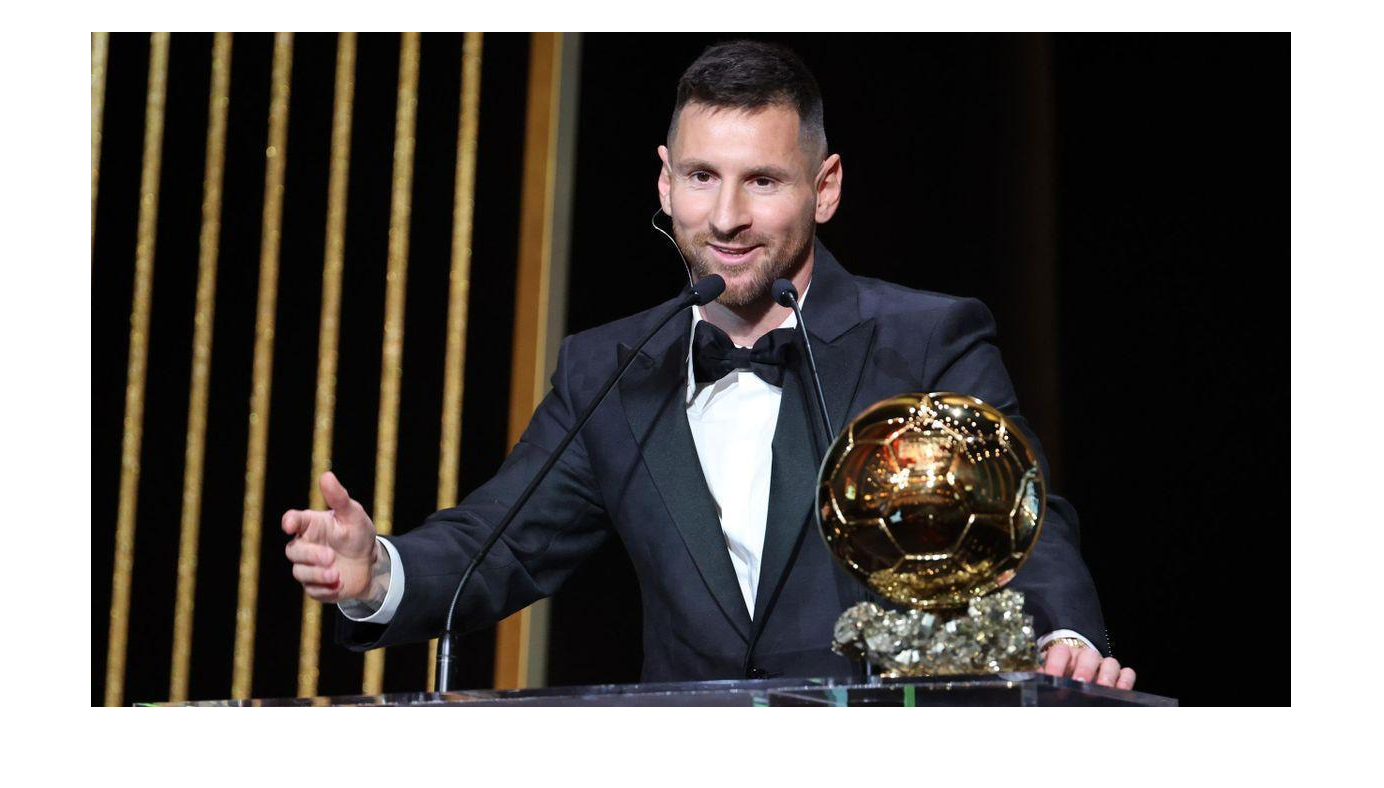

figure,imshow(Image);

% calculating the frequency of each pixels
[frequency,pixelValue]=imhist(Image());   
% suming all the frequencies
tf = sum(frequency) ;
% calculating the probability of each pixel
probability = frequency ./ tf ;
% creating the dictionary
dict=huffmandict(pixelValue,probability);   %generates binary huffmann code dictionary
% converting the image pixels to 1D array
imageOneD = Image(:)    %column wise hoga

imageOneD = 2430000×1 uint8 column vector
    98
   101
   105
   109
   112
   114
   114
   114
   111
   116


% encoding
testVal = imageOneD ;
encodedVal = huffmanenco(testVal,dict)

encodedVal =      1
     1
     1
     0
     0
     0
     0
     0
     1
     1


% decoding
decodedVal = huffmandeco(encodedVal,dict)

decodedVal =     98
   101
   105
   109
   112
   114
   114
   114
   111
   116


% displaying the length

kb = 8 * 1024 ;
disp(["before compression size is",numel(de2bi(testVal))/kb]) ;

    "before compression size is"    "2373.0469"



disp(["after compression size is",numel(encodedVal)/kb]) ;

    "after compression size is"    "1770.8347"



disp(["after reconstruction size is",numel(de2bi(decodedVal))/kb]) ;

    "after reconstruction size is"    "2373.0469"



% recovering the original image from 1D Array
[rows, columns, numberOfColorChannels]= size(Image);
oi = reshape(testVal,[rows, columns, numberOfColorChannels]) ;
imwrite(oi,'C:\Users\Sandeep\Downloads\messi.jpg');
% recovering the decoded image from 1D Array
decodedVal = uint8(decodedVal);
figure,imshow(decodedVal);